# exercise6_edge_detection_hallway.m

Exercise 6 – Edge detection & Hough transform on hallway.png

Author: ANGELOS NIKOLAOS POTAMIANOS Date : MAY 2025

clear; close all; clc;

## ------------------ Parameters ----------------------------------------

imgPath = fullfile('Images','Ασκηση 6','hallway.png');
thresholds = [0.1, 0.2, 0.3, 0.4];  % Multiple thresholds to test
save_results = true;                 % Flag to save result images

## ------------------ Load image ----------------------------------------

fprintf('Loading image from %s...\n', imgPath);

Loading image from Images\Ασκηση 6\hallway.png...


Irgb = imread(imgPath);
if ndims(Irgb)==3
    fprintf('Converting RGB to grayscale...\n');
    Igray = rgb2gray(Irgb);
else
    Igray = Irgb;
end
I = im2double(Igray);
fprintf('Image dimensions: %d x %d\n', size(I,1), size(I,2));

Image dimensions: 1168 x 1752


## 1. Sobel gradients ----------------------------------------------------

fprintf('\n--- STEP 1: Calculating Sobel gradients ---\n');


--- STEP 1: Calculating Sobel gradients ---


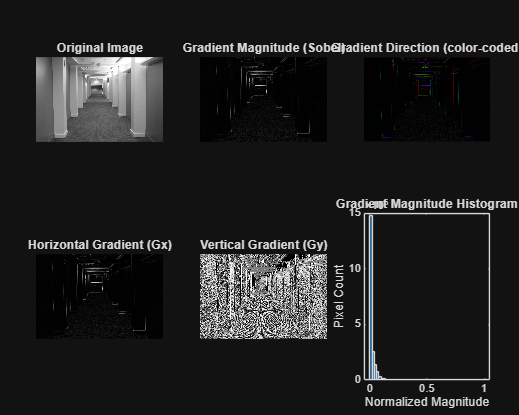


% Calculate both magnitude and direction
[Gmag, Gdir] = imgradient(I,'sobel');
% Also get separate X and Y gradients for visualization
[Gx, Gy] = imgradient(I,'sobel');

% Normalize for display
Gmag_norm = mat2gray(Gmag);
Gx_norm = mat2gray(abs(Gx));  % Take absolute for better visualization
Gy_norm = mat2gray(abs(Gy));

% Create visualization figure
figure('Name', 'Gradient Analysis', 'Position', [100, 100, 1000, 800]);
tiledlayout(2, 3, 'Padding', 'compact', 'TileSpacing', 'compact');

% Original image
ax1 = nexttile;
imshow(I);
title('Original Image');

% Gradient magnitude
ax2 = nexttile;
imshow(Gmag_norm);
title('Gradient Magnitude (Sobel)');

% Direction visualization using HSV color mapping
ax3 = nexttile;
hsv_img = zeros(size(I,1), size(I,2), 3);
hsv_img(:,:,1) = (Gdir + 180) / 360;  % Hue from direction
hsv_img(:,:,2) = ones(size(I));       % Full saturation
hsv_img(:,:,3) = Gmag_norm;           % Value from magnitude
rgb_dir = hsv2rgb(hsv_img);
imshow(rgb_dir);
title('Gradient Direction (color-coded)');

% X gradient
ax4 = nexttile;
imshow(Gx_norm);
title('Horizontal Gradient (Gx)');

% Y gradient
ax5 = nexttile;
imshow(Gy_norm);
title('Vertical Gradient (Gy)');

% Gradient statistics
ax6 = nexttile;
histogram(Gmag_norm(:), 50);
title('Gradient Magnitude Histogram');
xlabel('Normalized Magnitude');
ylabel('Pixel Count');

if save_results
    saveas(gcf, 'hallway_gradients.png');
end

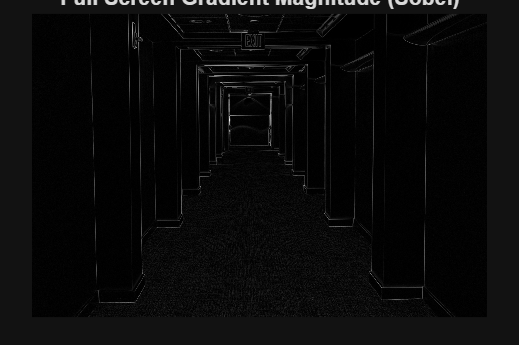


% Full-screen display of Sobel gradient magnitude
figure('Name', 'Sobel Gradient Magnitude - Full Screen', 'WindowState', 'maximized');
imshow(Gmag_norm);
title('Full Screen Gradient Magnitude (Sobel)', 'FontSize', 16);
if save_results
    saveas(gcf, 'hallway_gradient_fullscreen.png');
end


% Print statistics about the gradient
fprintf('Gradient statistics:\n');

Gradient statistics:


fprintf('  Maximum gradient magnitude: %.4f\n', max(Gmag(:)));

  Maximum gradient magnitude: 2.8628


fprintf('  Mean gradient magnitude: %.4f\n', mean(Gmag(:)));

  Mean gradient magnitude: 0.0696


fprintf('  Median gradient magnitude: %.4f\n', median(Gmag(:)));

  Median gradient magnitude: 0.0314


## 2. Global threshold (Otsu and alternatives) ---------------------------

fprintf('\n--- STEP 2: Edge Detection with Thresholding ---\n');


--- STEP 2: Edge Detection with Thresholding ---



% Calculate Otsu's threshold
T_otsu = graythresh(Gmag_norm);
fprintf('Otsu threshold = %.3f (%.1f%% of max)\n', T_otsu, T_otsu*100);

Otsu threshold = 0.125 (12.5% of max)


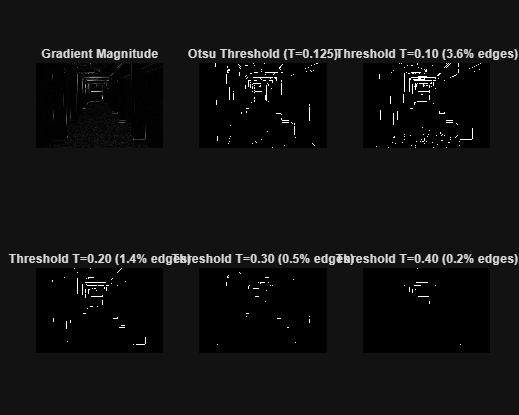


% Create a figure to compare different thresholds
figure('Name', 'Threshold Comparison', 'Position', [100, 100, 1000, 800]);
tiledlayout(2, 3, 'Padding', 'compact', 'TileSpacing', 'compact');

% Original gradient magnitude
ax1 = nexttile;
imshow(Gmag_norm);
title('Gradient Magnitude');

% Otsu threshold
BW_otsu = imbinarize(Gmag_norm, T_otsu);
ax2 = nexttile;
imshow(BW_otsu);
title(sprintf('Otsu Threshold (T=%.3f)', T_otsu));

% Test multiple thresholds
for i = 1:length(thresholds)
    T = thresholds(i);
    BW = imbinarize(Gmag_norm, T);
    
    % Calculate edge statistics
    edge_pixels = sum(BW(:));
    edge_percentage = 100 * edge_pixels / numel(BW);
    
    % Display result
    ax_i = nexttile(i+2);
    imshow(BW);
    title(sprintf('Threshold T=%.2f (%.1f%% edges)', T, edge_percentage));
end

if save_results
    saveas(gcf, 'hallway_thresholds.png');
end

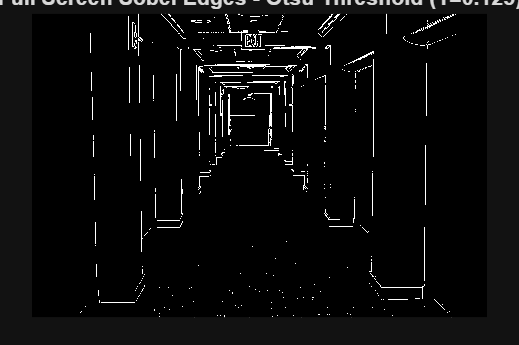


% Full-screen display of Otsu threshold result
figure('Name', 'Otsu Threshold Result - Full Screen', 'WindowState', 'maximized');
imshow(BW_otsu);
title(sprintf('Full Screen Sobel Edges - Otsu Threshold (T=%.3f)', T_otsu), 'FontSize', 16);
if save_results
    saveas(gcf, 'hallway_otsu_fullscreen.png');
end

## 3. BONUS – Hough Transform for Line Detection -------------------------

fprintf('\n--- STEP 3: Hough Transform for Line Detection ---\n');


--- STEP 3: Hough Transform for Line Detection ---



% Create Canny edges for better Hough input (cleaner edges)
fprintf('Generating Canny edges...\n');

Generating Canny edges...


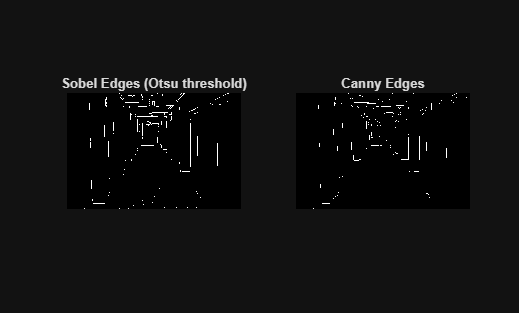

sigma = 2.0;  % Gaussian smoothing parameter to suppress texture
low_thresh = 0.05;  % Low threshold for hysteresis
high_thresh = 0.20; % High threshold for hysteresis
BWcanny = edge(I, 'canny', [low_thresh high_thresh], sigma);

% Compare Sobel vs Canny as input to Hough
figure('Name', 'Edge Detection Comparison');
subplot(1,2,1);
imshow(BW_otsu);
title('Sobel Edges (Otsu threshold)');

subplot(1,2,2);
imshow(BWcanny);
title('Canny Edges');

if save_results
    saveas(gcf, 'hallway_edges_comparison.png');
end

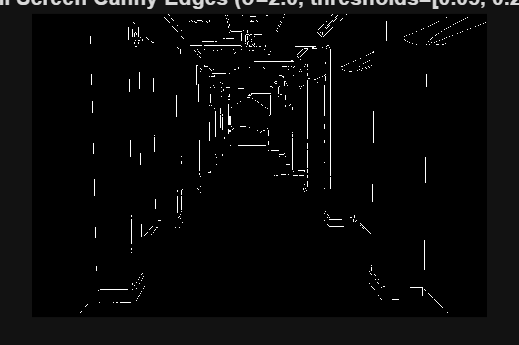


% Full-screen display of Canny edges
figure('Name', 'Canny Edges - Full Screen', 'WindowState', 'maximized');
imshow(BWcanny);
title('Full Screen Canny Edges (σ=2.0, thresholds=[0.05, 0.20])', 'FontSize', 16);
if save_results
    saveas(gcf, 'hallway_canny_fullscreen.png');
end


% Compute Standard Hough Transform
fprintf('Computing Hough transform...\n');

Computing Hough transform...


[H, theta, rho] = hough(BWcanny);

% Find peaks in Hough space
num_peaks = 12;
threshold_percentage = 0.30;
peak_threshold = threshold_percentage * max(H(:));
fprintf('Finding Hough peaks (threshold: %.1f%% of max)...\n', threshold_percentage*100);

Finding Hough peaks (threshold: 30.0% of max)...


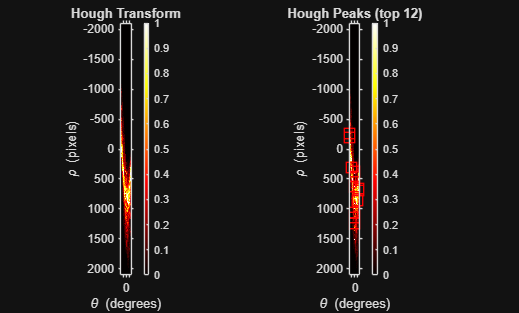

P = houghpeaks(H, num_peaks, 'Threshold', peak_threshold);

% Visualize Hough transform and peaks
figure('Name', 'Hough Transform Visualization');
subplot(1,2,1);
imshow(imadjust(mat2gray(H)), [], 'XData', theta, 'YData', rho);
title('Hough Transform');
xlabel('\theta (degrees)');
ylabel('\rho (pixels)');
axis on;
colormap(gca, hot);
colorbar;

% Overlay peaks on the Hough transform
subplot(1,2,2);
imshow(imadjust(mat2gray(H)), [], 'XData', theta, 'YData', rho);
title(sprintf('Hough Peaks (top %d)', num_peaks));
xlabel('\theta (degrees)');
ylabel('\rho (pixels)');
axis on;
colormap(gca, hot);
colorbar;
hold on;

% Mark the peaks with red circles
for k = 1:size(P,1)
    plot(theta(P(k,2)), rho(P(k,1)), 'rs', 'MarkerSize', 10, 'LineWidth', 1.5);
end

if save_results
    saveas(gcf, 'hallway_hough_transform.png');
end


% Extract line segments from peaks
fprintf('Extracting line segments...\n');

Extracting line segments...


fill_gap = 10;     % Maximum gap between edge segments
min_length = 60;   % Minimum line length to keep

lines = houghlines(BWcanny, theta, rho, P, 'FillGap', fill_gap, 'MinLength', min_length);
fprintf('Found %d line segments.\n', length(lines));

Found 19 line segments.



% Categorize lines by orientation
vertical_threshold = 80;    % Degrees from horizontal to be considered vertical
horizontal_threshold = 10;  % Degrees from horizontal to be considered horizontal

% Identify vertical and horizontal lines
is_vertical = abs([lines.theta]') > vertical_threshold;
is_horizontal = abs([lines.theta]') < horizontal_threshold;
vertical_lines = lines(is_vertical);
horizontal_lines = lines(is_horizontal);
other_lines = lines(~is_vertical & ~is_horizontal);

fprintf('Line categorization:\n');

Line categorization:


fprintf('  Vertical lines (|θ| > %d°): %d\n', vertical_threshold, sum(is_vertical));

  Vertical lines (|θ| > 80°): 2


fprintf('  Horizontal lines (|θ| < %d°): %d\n', horizontal_threshold, sum(is_horizontal));

  Horizontal lines (|θ| < 10°): 10


fprintf('  Other lines: %d\n', sum(~is_vertical & ~is_horizontal));

  Other lines: 7


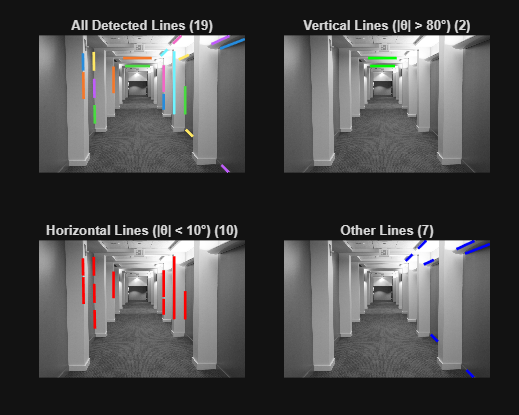


% Create a figure to visualize all detected lines
figure('Name', 'Line Detection Results', 'Position', [100, 100, 1000, 800]);
tiledlayout(2, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

% Original image with all lines
ax1 = nexttile;
imshow(Irgb);
hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2);
end
title(sprintf('All Detected Lines (%d)', length(lines)));

% Vertical lines only
ax2 = nexttile;
imshow(Irgb);
hold on;
for k = 1:length(vertical_lines)
    xy = [vertical_lines(k).point1; vertical_lines(k).point2];
    plot(xy(:,1), xy(:,2), 'g-', 'LineWidth', 2);
end
title(sprintf('Vertical Lines (|θ| > %d°) (%d)', vertical_threshold, length(vertical_lines)));

% Horizontal lines only
ax3 = nexttile;
imshow(Irgb);
hold on;
for k = 1:length(horizontal_lines)
    xy = [horizontal_lines(k).point1; horizontal_lines(k).point2];
    plot(xy(:,1), xy(:,2), 'r-', 'LineWidth', 2);
end
title(sprintf('Horizontal Lines (|θ| < %d°) (%d)', horizontal_threshold, length(horizontal_lines)));

% Other lines
ax4 = nexttile;
imshow(Irgb);
hold on;
for k = 1:length(other_lines)
    xy = [other_lines(k).point1; other_lines(k).point2];
    plot(xy(:,1), xy(:,2), 'b-', 'LineWidth', 2);
end
title(sprintf('Other Lines (%d)', length(other_lines)));

if save_results
    saveas(gcf, 'hallway_line_detection.png');
end

## 4. BONUS - Vanishing Point Analysis -------------------------

fprintf('\n--- STEP 4: Vanishing Point Analysis ---\n');


--- STEP 4: Vanishing Point Analysis ---


Estimating vanishing point from vertical lines...


Estimated vanishing point: (Inf, 262.0)


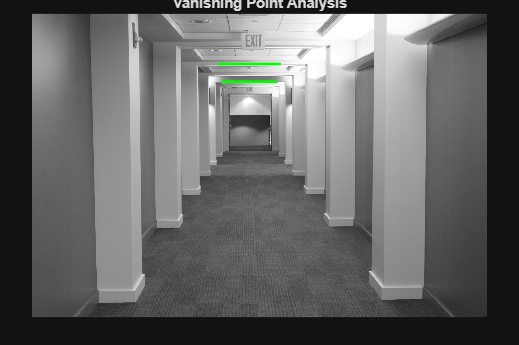

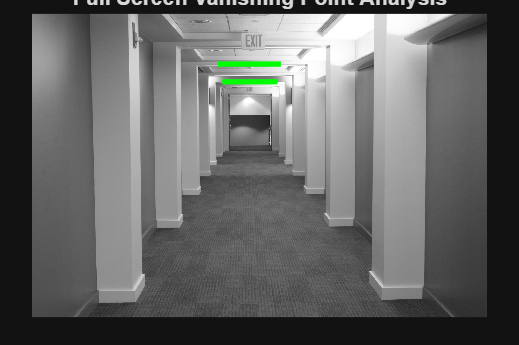


% Only proceed if we found enough lines
if length(vertical_lines) >= 2
    fprintf('Estimating vanishing point from vertical lines...\n');
    
    % Extract all endpoints from vertical lines for vanishing point estimation
    endpoints = vertcat(vertcat(vertical_lines.point1), vertcat(vertical_lines.point2));
    
    % Create line equations in parametric form: ax + by + c = 0
    line_params = zeros(length(vertical_lines), 3);
    
    for i = 1:length(vertical_lines)
        x1 = vertical_lines(i).point1(1);
        y1 = vertical_lines(i).point1(2);
        x2 = vertical_lines(i).point2(1);
        y2 = vertical_lines(i).point2(2);
        
        % Compute line parameters (ax + by + c = 0)
        if x2 ~= x1  % Not perfectly vertical
            a = (y2 - y1) / (x2 - x1);
            b = -1;
            c = y1 - a * x1;
        else  % Perfectly vertical line
            a = 1;
            b = 0;
            c = -x1;
        end
        
        line_params(i,:) = [a, b, c];
    end
    
    % Find the vanishing point (least squares approximation)
    % Set up system of equations for all lines
    A = line_params(:, 1:2);
    b = -line_params(:, 3);
    
    % Solve using least squares
    vp = A \ b;
    fprintf('Estimated vanishing point: (%.1f, %.1f)\n', vp(1), vp(2));
    
    % Create figure to visualize vanishing point
    figure('Name', 'Vanishing Point Analysis');
    imshow(Irgb);
    hold on;
    
    % Plot vertical lines used for VP estimation
    for k = 1:length(vertical_lines)
        xy = [vertical_lines(k).point1; vertical_lines(k).point2];
        plot(xy(:,1), xy(:,2), 'g-', 'LineWidth', 2);
    end
    
    % Highlight vanishing point
    if vp(1) >= 1 && vp(1) <= size(I,2) && vp(2) >= 1 && vp(2) <= size(I,1)
        % VP is within image boundaries
        plot(vp(1), vp(2), 'ro', 'MarkerSize', 15, 'LineWidth', 3);
    else
        % VP is outside image - show direction
        img_center = [size(I,2)/2, size(I,1)/2];
        direction = vp - img_center;
        direction = direction / norm(direction) * min(size(I,1), size(I,2)) / 3;
        quiver(img_center(1), img_center(2), direction(1), direction(2), 0, 'r', 'LineWidth', 3);
    end
    
    title('Vanishing Point Analysis');
    
    if save_results
        saveas(gcf, 'hallway_vanishing_point.png');
    end
    
    % Full-screen display of vanishing point
    figure('Name', 'Vanishing Point Analysis - Full Screen', 'WindowState', 'maximized');
    imshow(Irgb);
    hold on;
    
    % Plot vertical lines used for VP estimation with thicker lines
    for k = 1:length(vertical_lines)
        xy = [vertical_lines(k).point1; vertical_lines(k).point2];
        plot(xy(:,1), xy(:,2), 'g-', 'LineWidth', 4);
    end
    
    % Highlight vanishing point with larger marker
    if vp(1) >= 1 && vp(1) <= size(I,2) && vp(2) >= 1 && vp(2) <= size(I,1)
        % VP is within image boundaries
        plot(vp(1), vp(2), 'ro', 'MarkerSize', 20, 'LineWidth', 4);
    else
        % VP is outside image - show direction with thicker arrow
        img_center = [size(I,2)/2, size(I,1)/2];
        direction = vp - img_center;
        direction = direction / norm(direction) * min(size(I,1), size(I,2)) / 3;
        quiver(img_center(1), img_center(2), direction(1), direction(2), 0, 'r', 'LineWidth', 4);
    end
    
    title('Full Screen Vanishing Point Analysis', 'FontSize', 16);
    
    if save_results
        saveas(gcf, 'hallway_vanishing_point_fullscreen.png');
    end
else
    fprintf('Not enough vertical lines to estimate vanishing point.\n');
end